### Introduction to Environmental Data Analysis and Statistical Learning 

### Exercise 6 – Bayesian learning

### Ka Hei Pinky, Chow

clear all
close all
clc

load ue_06_bayesian_learning_data
whos

  Name           Size             Bytes  Class     Attributes

  Q_COL      43466x1             347728  double              
  Q_USL      43466x1             347728  double              



Method 1: Least Square Linear Regression

%assume Q_USL = a * Q_COL + b
a = polyfit(Q_COL,Q_USL,1); 

display("Hence, a = " + a(1) + " and b = " + a(2));

    "Hence, a = 8.2007 and b = 1.0203"



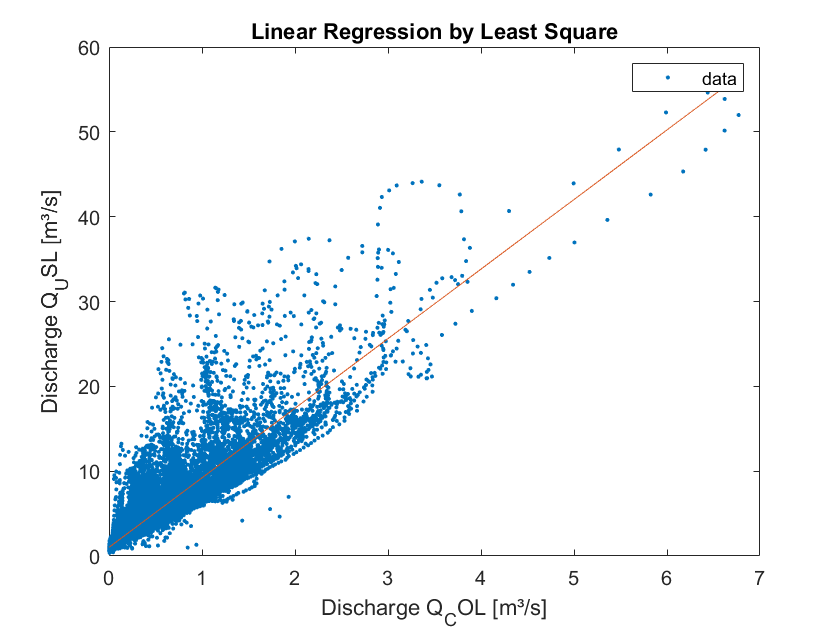

y = polyval(a,Q_COL);
figure
plot(Q_COL,Q_USL,'.')
hold on
plot(Q_COL,y)
hold off
xlabel("Discharge Q_COL [m³/s]")
ylabel("Discharge Q_USL [m³/s]")
title("Linear Regression by Least Square")
legend("data")

Results: a = 8.2007; b = 1.0203

Method 2: Bayesian Learning

% define some variables
a2 = 1:0.1:20; %the range of the hypothesis
b2 = 1.0203; %[m³/s]
num_obs = length(Q_USL); %number of observation

%Construct the prior probability distribution of model
num_h = length(a2);  %the length of model (hypothesis)
p_prior = ones(num_h,1);
p_prior = p_prior*(1/num_h); %uniform distribution of probability

% construct the likelihood functions for each hypothesis
% rows = model (hypothesis), cols = height of the normpdf

One-by-one bayesian learning

% loop over all observations
for o = 1 : num_obs %number of obs
    %Q_USL = a2 * Q_COL + b2
    %Q_USL_sim (simulated Q_USL) = [1:0.1:20] * Q_COL + 1.0203
    Q_USL_sim = a2 * Q_COL(o) + b2; %from obs of Q_COL
    num_o = length(Q_USL_sim); %number of outcome = number of simulation results
    sigma = 10; %standard deviation = 10 (given)
    likelihood = normpdf(Q_USL_sim,Q_USL(o),sigma); 
    % assume normal distribution P(E) of observation
    % mean = obs value (Q_USL)
    
    % calculate the marginal probability of the observation by summing up,
    % over all models, the likelihood of the observation multiplied by the occurrence
    % probability of the model (prior)
    
        p_observation = 0; % initialize the marginal probability of the observation

        % loop over all models
        for m = 1 : num_h
            p_observation = p_observation + likelihood(m) * p_prior(m);
        end
        
    % apply Bayes' theorem to get the posterior probabiltiy of the
    % models given the observation
    
        p_posterior = NaN(num_h,1); % initialize the array for posterior distribution of models
        % loop over all models
        for m = 1 : num_h
            p_posterior(m) = ( likelihood(m) * p_prior(m) ) / p_observation;
        end
    
    % update the probability distribution of models
    p_prior = p_posterior;
    
    % express the progress
    if rem(o,500) == 0
        display("running..." + round(o*100/length(Q_USL)) + "%")
    end
  
end

    "running...1%"

    "running...2%"

    "running...3%"

    "running...5%"

    "running...6%"

    "running...7%"

    "running...8%"

    "running...9%"

    "running...10%"

    "running...12%"

    "running...13%"

    "running...14%"

    "running...15%"

    "running...16%"

    "running...17%"

    "running...18%"

    "running...20%"

    "running...21%"

    "running...22%"

    "running...23%"

    "running...24%"

    "running...25%"

    "running...26%"

    "running...28%"

    "running...29%"

    "running...30%"

    "running...31%"

    "running...32%"

    "running...33%"

    "running...35%"

    "running...36%"

    "running...37%"

    "running...38%"

    "running...39%"

    "running...40%"

    "running...41%"

    "running...43%"

    "running...44%"

    "running...45%"

    "running...46%"

    "running...47%"

    "running...48%"

    "running...49%"

    "running...51%"

    "running...52%"

    "running...53%"

    "running...54%"

    "running...55%"



Plotting the final probability distribution of a

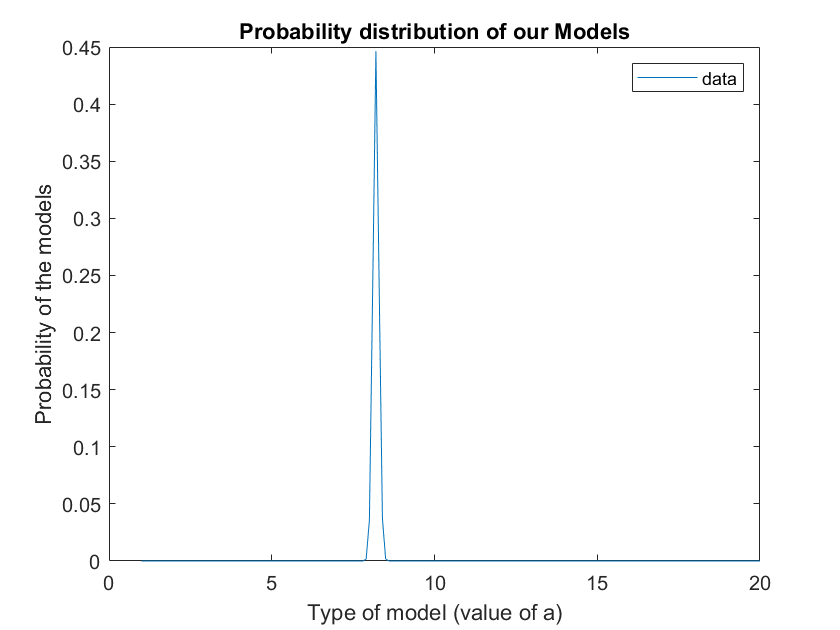

%Plotting the final probability distribution of a
plot(a2, p_prior)
xlabel("Type of model (value of a)")
ylabel("Probability of the models")
title("Probability distribution of our Models")
legend("data")

Find the value of a with the highest posterior probability

[max_value, idx] = max(p_prior);
a_BL = a2(idx);

display("The value of a from Least squares regression is: " + a(1))

    "The value of a from Least squares regression is: 8.2007"



display("The value of a from Bayesian learning model is: " + a_BL)

    "The value of a from Bayesian learning model is: 8.2"



Observation: 

The "a" value obtained form the least squares regression (a = 8.2) is close to the "a" value obtained in the Bayesian learning model (a = 10). It implies without using the frequentist approach, we can also use the introduction of prior value to formulate linear regression with probability distribution.

Plotting Results from both Methods

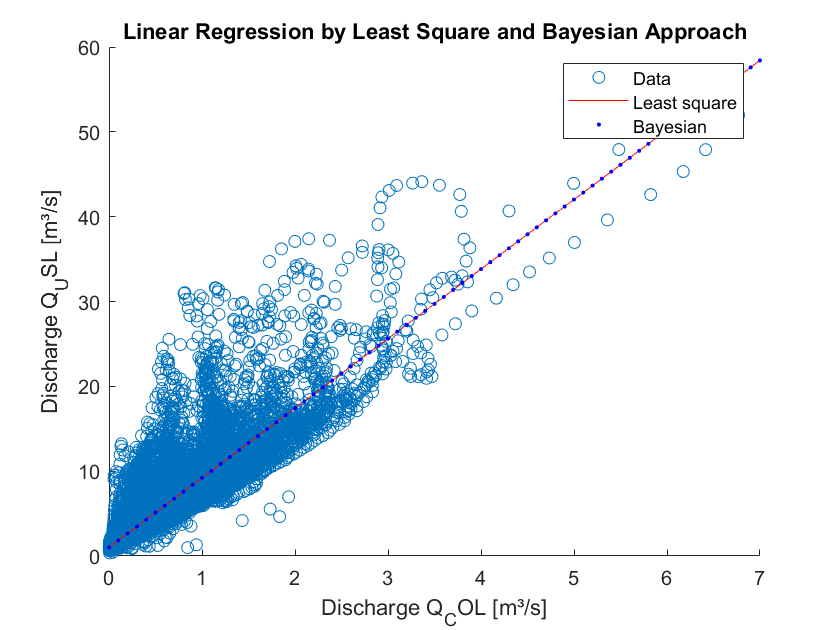

figure
hold on 
scatter(Q_COL,Q_USL,"o")

x1 = 0:0.1:round(max(Q_COL)); %Least square
y1 = a(1)*x1 + a(2);
plot(x1,y1,"-",'color','r')

x2 = 0:0.1:round(max(Q_COL)); %Bayesian
y2 = a_BL*x1 + b2;
plot(x2,y2,".",'color','b')
hold off

xlabel("Discharge Q_COL [m³/s]")
ylabel("Discharge Q_USL [m³/s]")
title("Linear Regression by Least Square and Bayesian Approach")
legend("Data","Least square","Bayesian")